## **Principles of Biosignals and Biomedical Imaging**

### **P3, 2nd Semester 2022/2023**

# **Image Processing of Dermoscopic Images**

## MATLAB Project

### **Instituto Superior Técnico**

***100290, Armando Gonçalves***

***100357, Patrícia Marques***

# **1) Methods**

1)

% Define the folder path where the images are stored
folderPath = 'Data';

% Create an imageDatastore object to read all the .jpg images from the folder
imds = imageDatastore(folderPath, 'FileExtensions', '.jpg');

% Read all the images and convert them to grayscale and invert them
imds = readall(imds);
imds = cellfun(@(x) imcomplement(rgb2gray(x)), imds, 'UniformOutput', false);

% 'UniformOutput' is set to false to tell cellfun every output of the cell
% may note be uniform in size or shape

2)

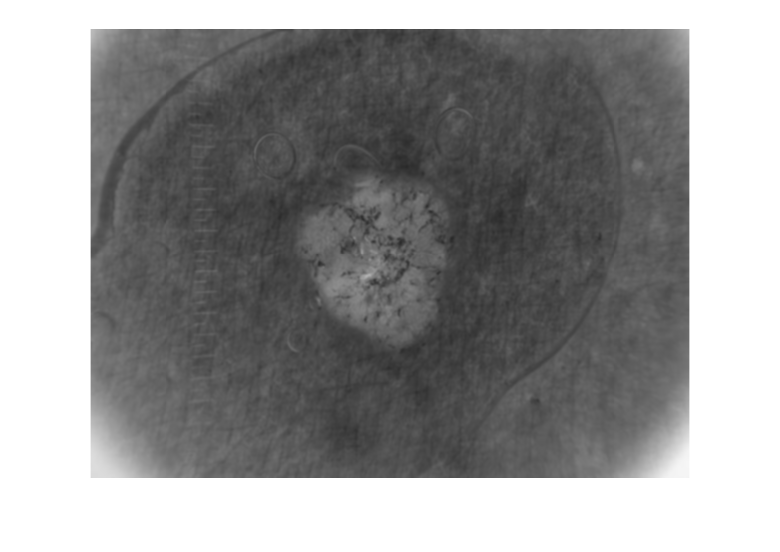

% Define the standard deviation and filter size of the Gaussian filter
sigma = 1;
filterSize = 5;

% Apply a Gaussian filter to each image in the cell array
imds_filtered = cellfun(@(x) imgaussfilt(x, sigma, 'FilterSize', filterSize), imds, 'UniformOutput', false);

% Display the first denoised image
imshow(imds_filtered{1})